p0 = 1;
N = 10;

i = 0;
while (i < N)
    % escape the loop if p is the root
    if myfun(p0) == 0
        break
    end

    % compute p
    p = p0 - (myfun(p0) / d_myfun(p0));

    % escape the loop if relative difference is smaller than 10^(-3)
    if (rel_dif(p0, p) < 10^(-3))
        p0 = p;
        break
    end

    %update i
    i = i + 1;

    % update p0
    p0 = p;

end

% print
fprintf("Aprroximated root is %f\n", p0);

Aprroximated root is 1.306327

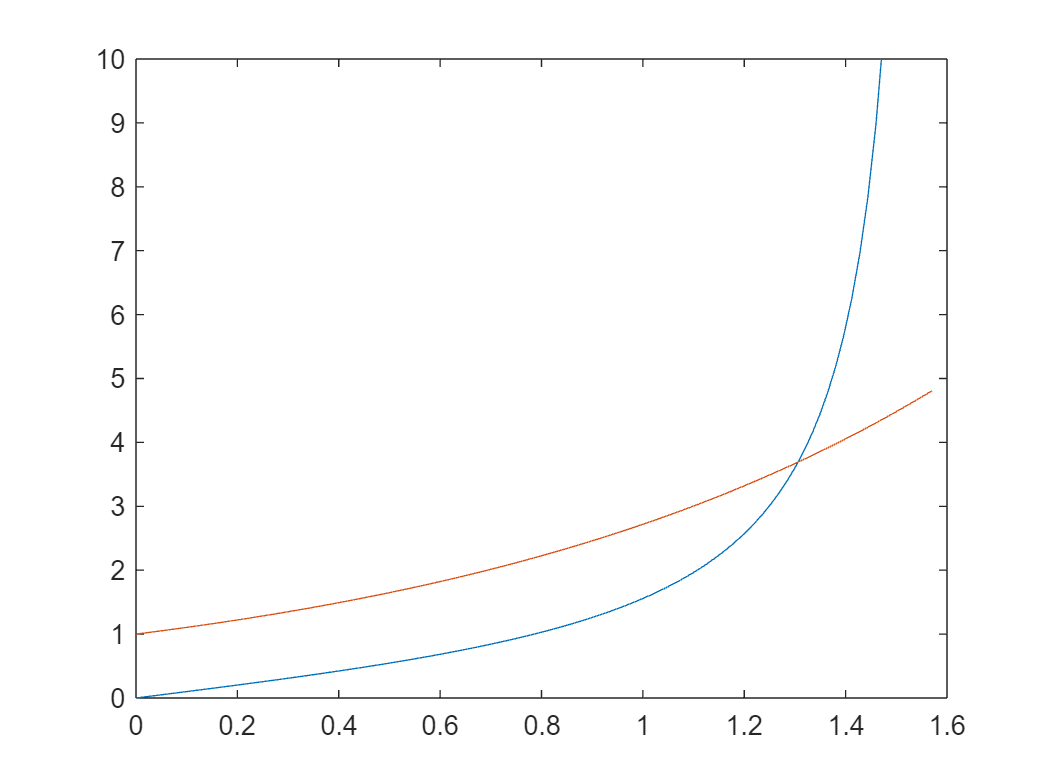


% display the graph
x = linspace(0,pi/2);
y1 = tan(x);
y2 = exp(x);
plot(x,y1,x,y2)
ylim([0 10])

function dif = rel_dif(x1, x2)
    dif = abs(x2-x1)/abs(x1);
end

function val = myfun(x)
    val = tan(x) - exp(x);
end

function val = d_myfun(x)
    val = 1/(cos(x)^2) - exp(x);
end

